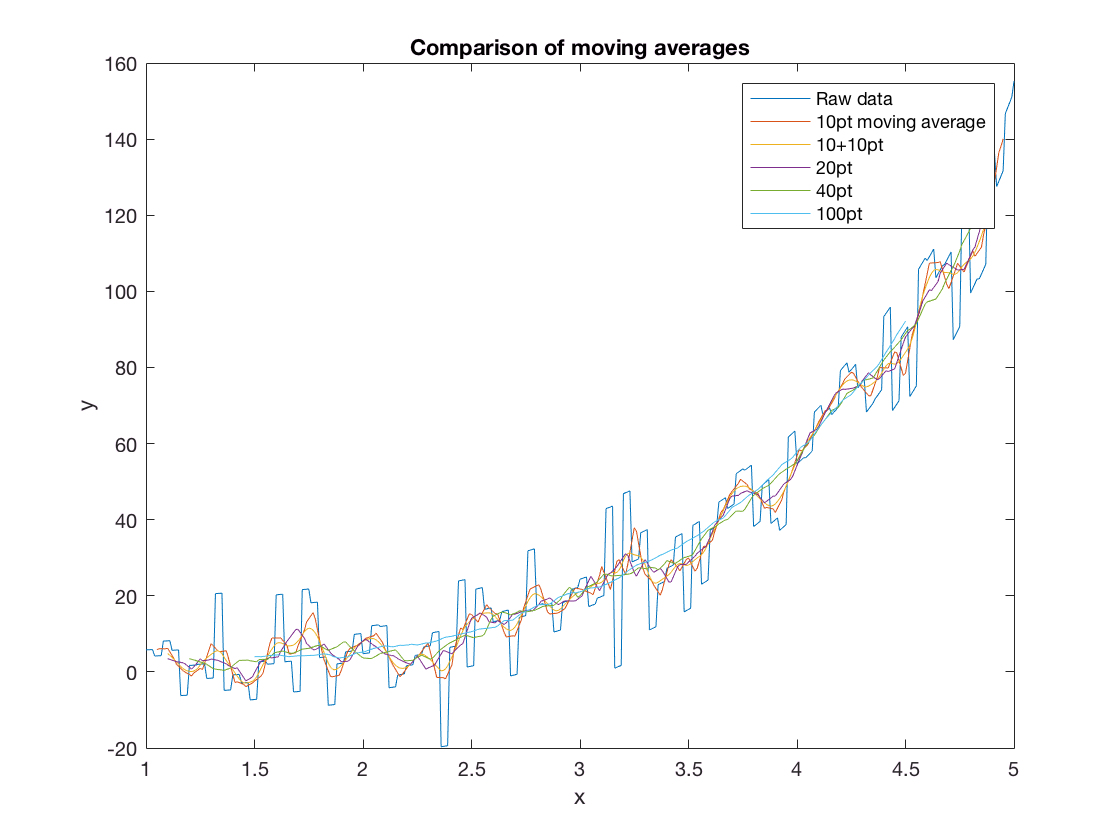

% Fonte:
% http://matlaboratory.blogspot.com.br/2015/03/alternative-function-simple-moving.html

% Create xaxis
x=1:0.01:5;
% Generate noise
noiseReps = 4;
noise = repmat(randn(1,ceil(numel(x)/noiseReps)),noiseReps,1);
noise = reshape(noise, 1, length(noise)*noiseReps);
% Generate ydata + noise
y=exp(x)+10*noise(1:length(x));
% Perfrom averages:
y2 = movAv(y, 10); % 10 pt
y3 = movAv(y2, 10); % 10+10 pt
y4 = movAv(y, 20); % 20 pt
y5 = movAv(y, 40); % 40 pt
y6 = movAv(y, 100); % 100 pt
% Plot
figure
plot(x,[y', y2', y3', y4', y5', y6'])
legend('Raw data', '10pt moving average', '10+10pt', '20pt', '40pt', '100pt')
xlabel('x');
ylabel('y');
title('Comparison of moving averages')